# Ex02. パッチ1枚分の体積の計算

このプロジェクトの最終目標である3Dラドン変換は、等間隔に3Dモデルを分割し体積計算を行うことです。

1章より、STLファイル形式の3Dモデルは三角形のパッチの集合で構成されていることが分かります。

そのため、パッチごとに体積計算を行うことでモデル全体の体積を求めます。

この章では、以下の手順に沿って、パッチ1枚の体積を計算することを考えます。

- stlファイルの読み込み

- 三角柱の体積計算

- パッチと分割面の交点座標の計算

- 分割区間に含まれる多面体の体積計算

- 垂線による体積の正負の判定

## 1. STLファイルの読み込み

まずは前回の内容を参考に、現在のフォルダーの確認を行ってください。

次に、STLファイルの読み込みを行います。

前回の内容を参考に、以下にコードを書き3Dモデルを読み込んでください。

clear % ワークスペースの初期化

file_path = "sampleModel.stl";
%TR = []; % この行を書き換える
TR = stlread(file_path);

コードが書けたら実行してみましょう。

以下のプログラムは、STLファイルが正しく読み込めているかをテストします。

assert(all(size(TR.Points) == [672, 3]))
assert(all(size(TR.ConnectivityList) == [1344, 3]))

実行時にエラーが出なければ成功です。

今後の課題では、このようにテストコードが書かれています。

すべてのテストコードをパスすることを目標にしてください。

## 2. 切頭三角柱の体積計算

初めに、モデルの体積計算に必要となる三角柱の体積を求めるコードを実装してみましょう。

ここでは、与えられた三角面の各頂点 $P_1, P_2 , P_3$ からxy平面に垂線を下してできる切頭三角柱について考えます。

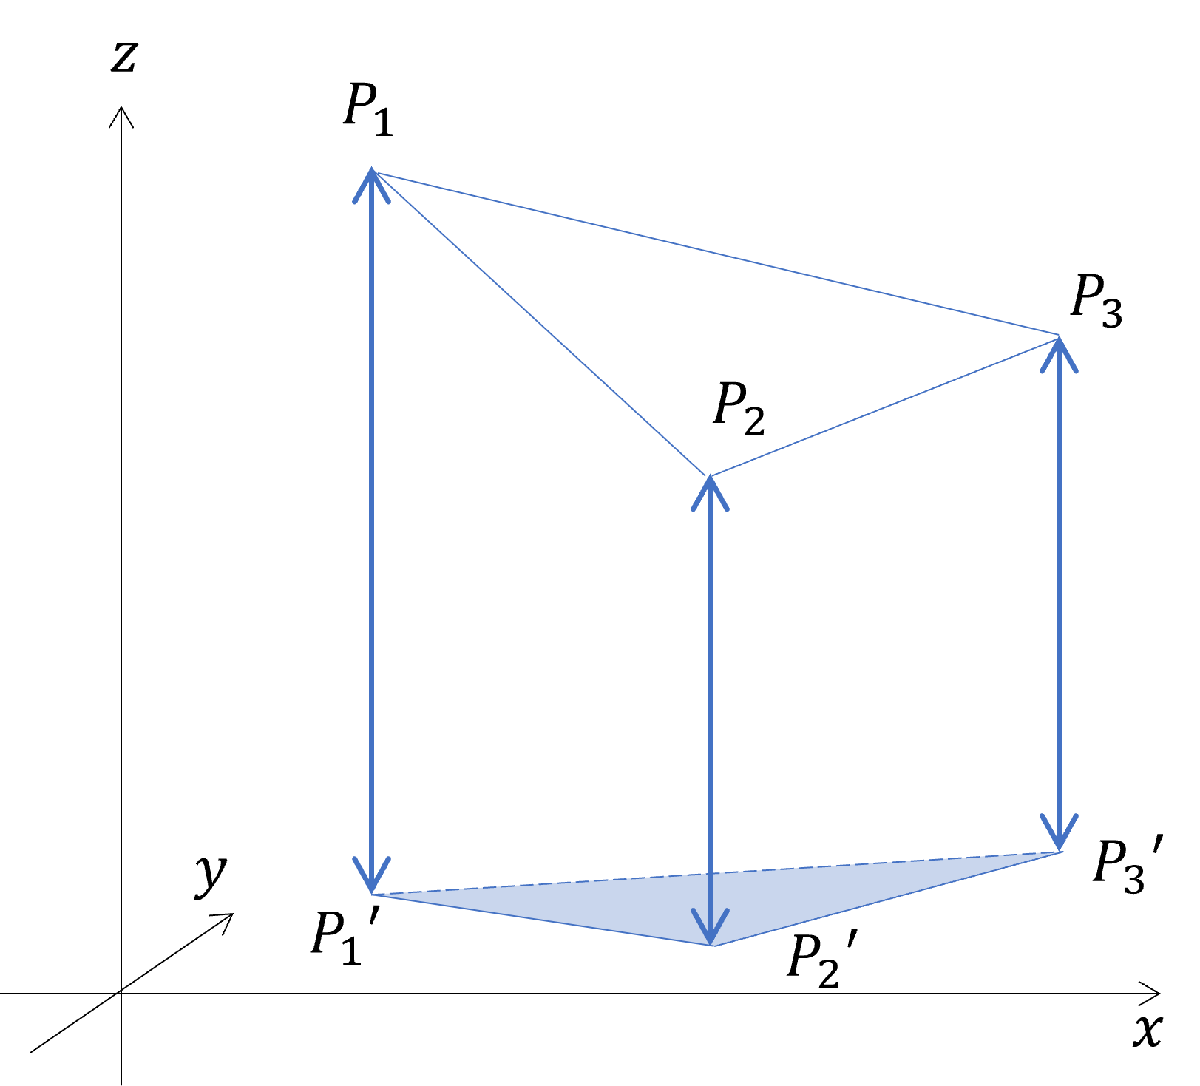

 calc_volume.m を書き換えて、三角柱の体積を計算する関数を完成させてください。

三角柱を3つの三角錐に分解する手法や外積を使う手法など、いくつか方法があるので自分がいいと思う手法で実装してみてください。

引数 p1、p2、p3 は三角面の各頂点の xyz 座標である 1×3 の配列、返り値 vl は三角柱の体積のスカラーとします．

また、ここでは与えられる三角面の頂点の z 座標が正の場合のみを考えます。

テストコード

tol = 1e-4;

アサーションに失敗しました。

p1 = [8.1472, 9.0579, 1.2699];
p2 = [13.9249, 27.3441, 47.8753];
p3 = [19.1433, 9.7075, 16.0056];
assert(abs(calc_volume(p1, p2, p3) - 2142.6327) < tol)
% 別のパッチ
p1 = [8.1472, 9.0579, 1.2699];
p2 = [13.9249, 9.0579, 47.8753];
p3 = [19.1433, 9.0579, 16.0056];
assert(calc_volume(p1, p2, p3) < tol)
% 別のパッチ
p1 = [6.7874, 7.5774, 7.4313];
p2 = [3.9223, 6.5548, 1.7119];
p3 = [7.0605, 0.3183, 2.7692];
assert(abs(calc_volume(p1, p2, p3) - 41.8469) < tol)


## 3. モデル全体の体積計算

このプロジェクトで実装するラドン変換では、3Dモデルを構成するパッチの各頂点からxy平面に垂線を下してできる切頭三角柱の体積（パッチの体積）を計算し、足し合わせることでモデル全体の体積を求めます。

モデルを分割したときの断面図を用いて、下図に計算方法の一例を示します。

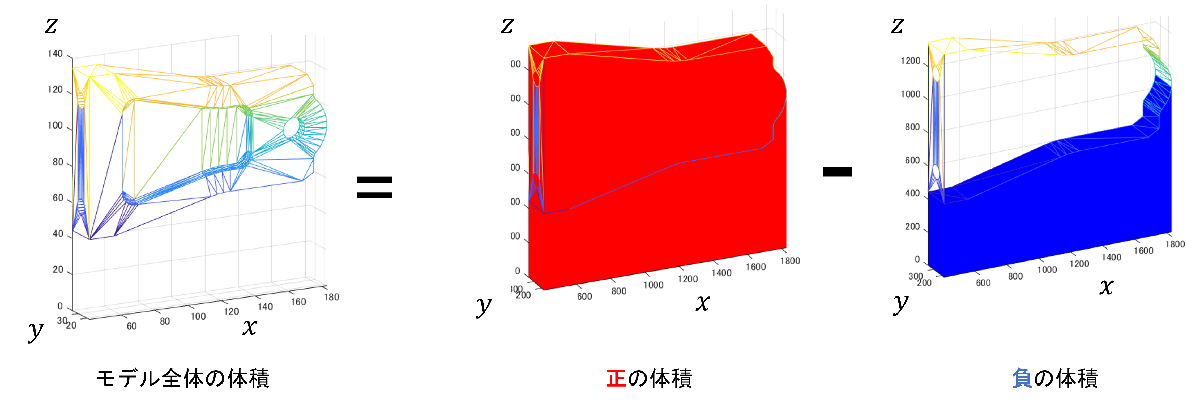

$z > 0
$ にモデルがあるとき、パッチ毎に体積を計算し、その体積をプラスにするかマイナスにするを決めて，足し合わせることでモデル全体の体積を計算することが出来ます。

よって，パッチ体積 ( > 0) を計算したあと，その体積を正の体積にするか，負の体積にするかを決める必要があります．

## パッチの裏表

パッチには裏表の向きがあります。

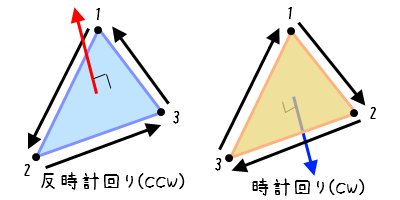

ConnectivityList で定義されている頂点の順番によって、Patchの「法線ベクトル」の向きが決まります。

「法線ベクトル」の向いている方向が表です。

「法線ベクトル」は右ネジの法則のように、頂点が反時計周りのときは上向き、時計回りのときは下向きです。

これは triangulation だけの仕様ではなく、STLファイルでも、その他の様々な3Dモデル形式でも同様に使われる定義です。

よってパッチ体積の正負は、法線ベクトルのz成分の正負と同じにすれば良いです．

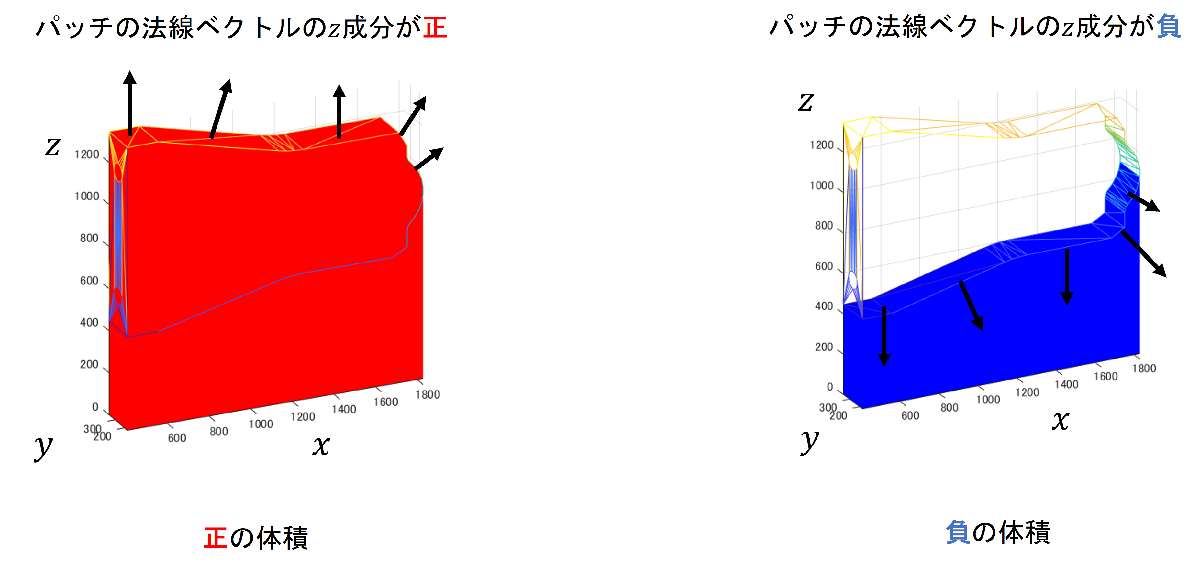

では、具体例を見てみましょう。以下のコードを実行してみてください．

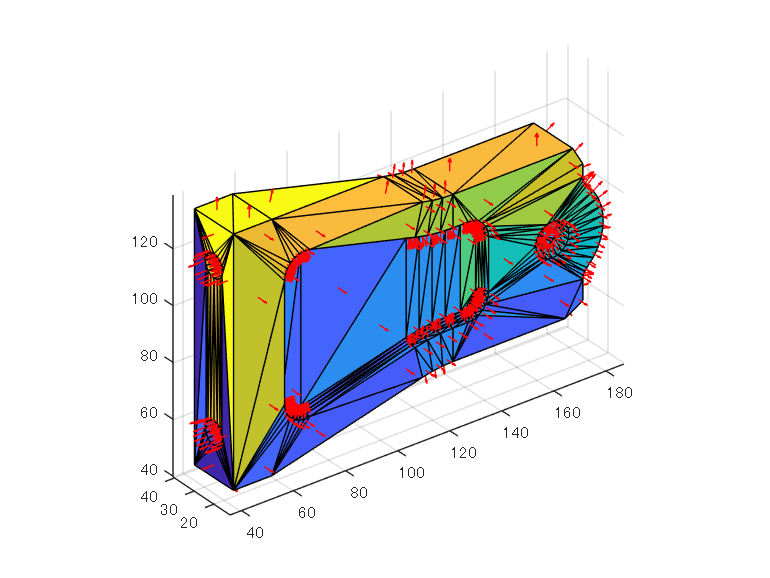

P = incenter(TR); % 各Patchの中心 (内心)
F = faceNormal(TR); % 各Patchの法線ベクトル


trisurf(TR)
axis equal % XYZの目盛りを1:1:1に
hold on  
quiver3(P(:,1),P(:,2),P(:,3), F(:,1),F(:,2),F(:,3), 1, 'color', 'r');

出力された図で分かるように、一般に各パッチの法線はモデルの外側を向くように設定されています。

パッチの裏表は、「法線ベクトル」を使って計算できます。

法線ベクトルは、上のコードのように faceNormal(TR) を使って計算することもできますが、

パッチ1枚毎にこれを行うのは非効率なので、外積 ( MATLAB: cross() ) などを使って自前で計算してください。

## 外積とは

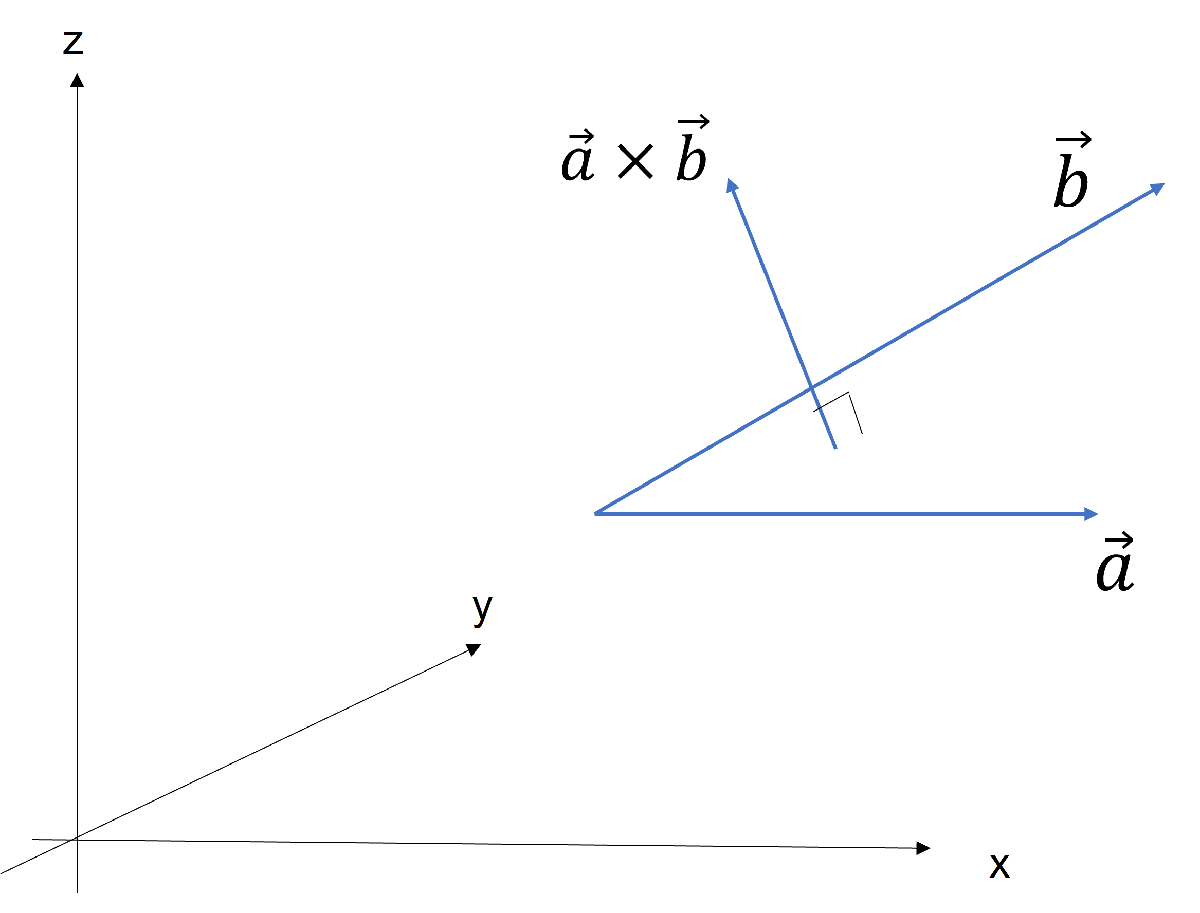

外積とは，ベクトル $\vec{a}\times\vec{b}
$のことです．$\times$ は掛け算ではない別の演算子です．

ベクトル $\vec{a}\times\vec{b}
$ が外積です．上の図のように，$\vec{a}$と$\vec{b}
$が伸びている場合，$\vec{a}\times\vec{b}$ がこの方向に伸びることを覚えといてください．

matlab では cross(a, b) で計算できます．

### 課題：下の三角形 p1, p2, p3 において，表方向に垂直なベクトルを求めましょう．

以下のコードを修正して，実行してください．p1 p2 p3 から外積計算できるように，ベクトルにしましょう．

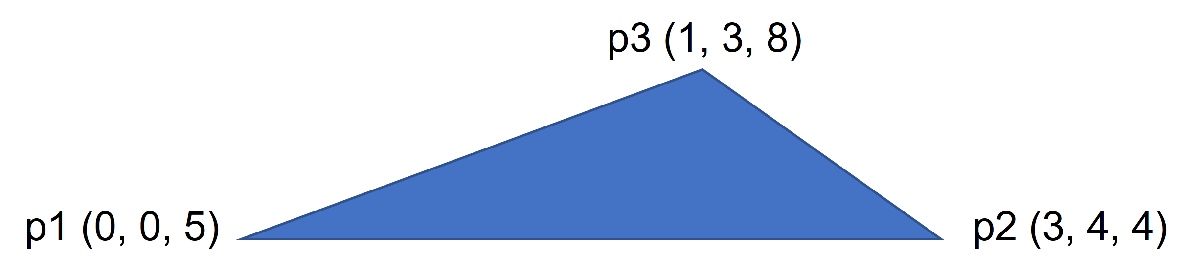

p1 = [0, 0, 5];
p2 = [3, 4, 4];

入力引数が不足しています。

エラー: cross (行 26)
if isvector(a) && isvector(b)

p3 = [1, 3, 8];

%%% ↓　表方向に垂直なベクトル (法線ベクトル：normal) を計算 %%%%%%%%%%%%%%%%%
normal = cross(); % ←　正しく書きましょう．
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%



テストコード

assert(norm(normal - [15, -10, 5]) < 1e-5); 

figure;
P = [
    p1;
    p2;
    p3;
    ];
trimesh([1,2,3], P(:,1), P(:,2), P(:,3), FaceColor='b', FaceAlpha=0.5);
text(p1(1), p1(2), p1(3), 'p1', FontSize=20);
text(p2(1), p2(2), p2(3), 'p2', FontSize=20);
text(p3(1), p3(2), p3(3), 'p3', FontSize=20);
hold on;
quiver3(mean(P(:,1)), mean(P(:,2)), mean(P(:,3)), normal(1)/sum(normal), normal(2)/sum(normal), normal(3)/sum(normal), "off", LineWidth=2);
axis equal;
xlabel('x', FontSize=20); ylabel('y', FontSize=20); zlabel('z', FontSize=20, Rotation=0);
view([-10.33 25.73])

法線ベクトルが正しい方向に垂直に伸びていれば ok です．

## 実際にモデル全体の体積を求める

### 課題：Ex02 のまとめです．モデル全体の体積 volume (配列ではない) を求めます．

以下のコードを基に作成してください．

TR = stlread("sampleModel.stl");
p = TR.Points;
c = TR.ConnectivityList;
volume = 0;

% ↓ c_idx は頂点連結リストの行番号
for c_idx = 1:height(c)
    % ↓ c_list に c_idx 行目のリストを代入
    c_list = c(c_idx, :);

    % ↓　c_list の１番目の頂点 p1 = [x, y, z]; を作成
    p1 = p(c_list(1),:);
    % ↓ c_list の２番目の頂点 p2 = [x, y, z]; を作成
    p2 = p(c_list(2),:);
    % ↓ c_list の３番目の頂点 p3 = [x, y, z]; を作成
    p3 = p(c_list(3),:);

    % 外積を計算
    normal = cross(p2 - p1, p3 - p1);

    
    if normal(3) > 0 % ← 法線ベクトルが上向きのとき

        %%%%%% ↓ calc_volume() の括弧内を正しく書き換えましょう %%%%%%%%
        volume = volume + calc_volume();
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    elseif normal(3) < 0 % ← 法線ベクトルが下向きのとき

        %%%%%% ↓ calc_volume() の括弧内を正しく書き換えましょう %%%%%%%%
        volume = volume - calc_volume();
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    else % ← 法線ベクトルの z が 0 のとき
        continue; % ← continue は continue 以降の処理を飛ばすして次のループに入るという意味．
    end
end


テストコード

assert(abs(volume - 148107) < 0.1)